clear all;
load fisheriris.mat


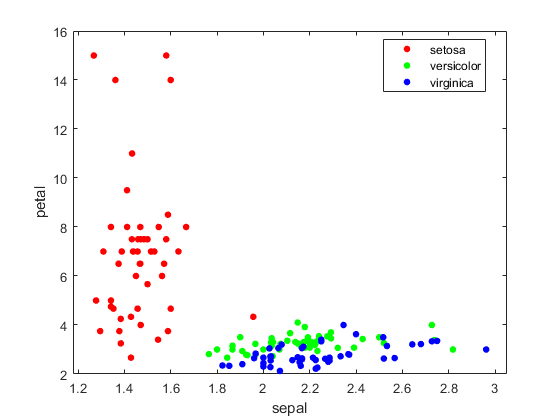

meas;
species;
sepal = meas(: , 1) ./ meas(: , 2);
petal = meas(: , 3) ./ meas(: , 4);
gscatter(sepal, petal, species);

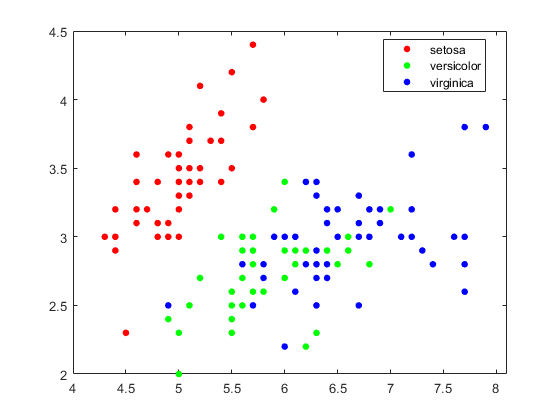

gscatter(meas(:, 1), meas(: , 2) , species);

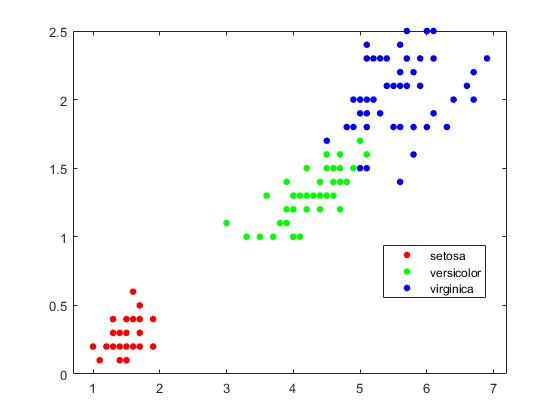

gscatter(meas(:, 3), meas(: , 4) , species);

cv = cvpartition(species, "HoldOut", 0.2)

cv = Hold-out cross validation partition
   NumObservations: 150
       NumTestSets: 1
         TrainSize: 120
          TestSize: 30

trainMeasure = meas(cv.training, :);
trainSpecies = species(cv.training, :);
testMeasure = meas(cv.test, :);
testSpecies = species(cv.test, :);


Model = fitcknn(trainMeasure, trainSpecies, "NumNeighbors", 5, "Standardize", 1)

Model =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'setosa'  'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 120
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


pred = predict(Model, testMeasure);
predString = string(pred);
correct = predString == testSpecies;
accuracy = sum(correct)/numel(pred);

wrong = predString ~= testSpecies;
misclassrate = sum(wrong)/numel(pred)

misclassrate = 0

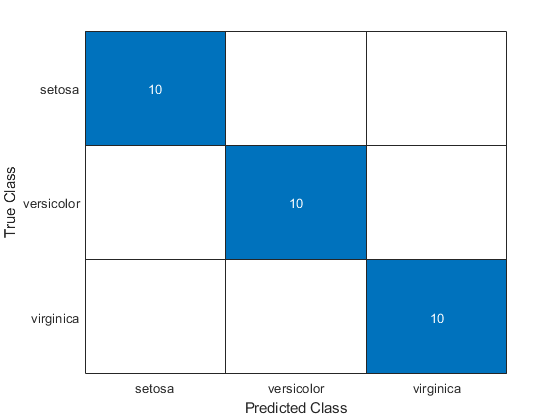

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: {3×1 cell}

  Show all properties



confusionchart(testSpecies, pred)